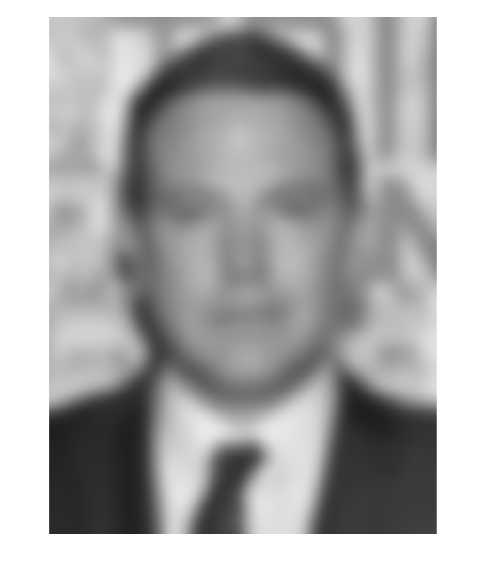

%%% 1. %%%
sigma=18.0;  % use different values 
G = fspecial('gaussian', 2*ceil(3*sigma)+1, sigma); 
faceIm = double(imread('affleck_gray.png')); 
gIm = imfilter(faceIm, G, 'replicate'); 
imshow(gIm/255);  % double images need range of 0-1

imwrite(uint8(gIm), 'gIm.bmp');

The face becomes recognizable around sigma=18.

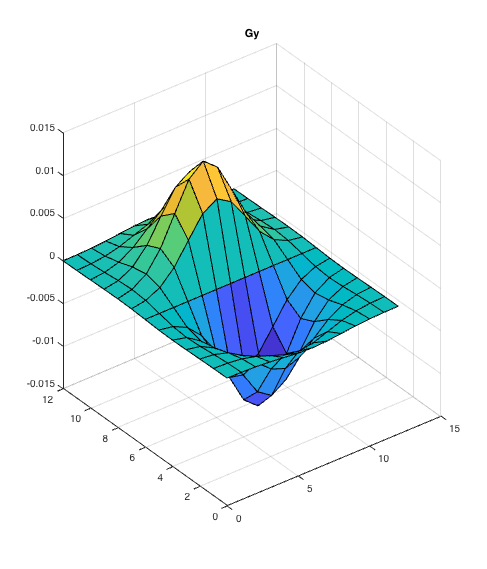

%%% 2. %%%%
[Gx, Gy] = gaussDeriv2D(2);

I thought it was cool that you can see how the value of sigma affects the "resolution" of the gaussian. This made it easier to understand how the sigma value affects the amount of smoothing that occurs. 

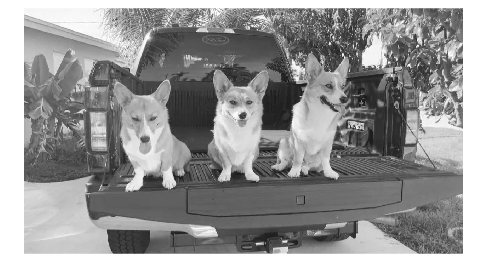

%%% 3. %%%%
myIm = double(rgb2gray(imread('test.jpg'))) / 255;
imshow(myIm);

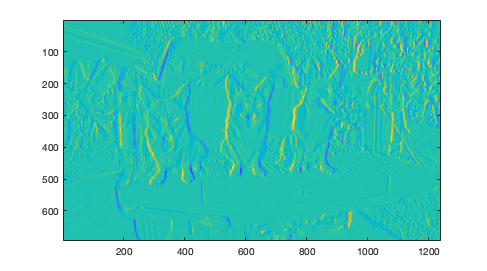

gxIm = imfilter(myIm, Gx, 'replicate'); 
gyIm = imfilter(myIm, Gy, 'replicate'); 
magIm = sqrt(gxIm.^2 + gyIm.^2); 
imagesc(gxIm);

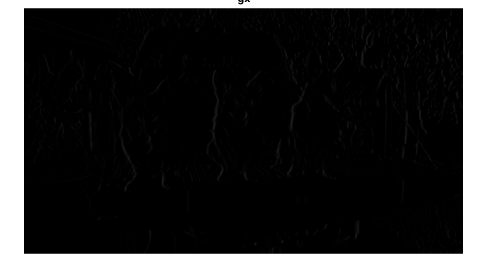

imshow(gxIm);
title('gx');

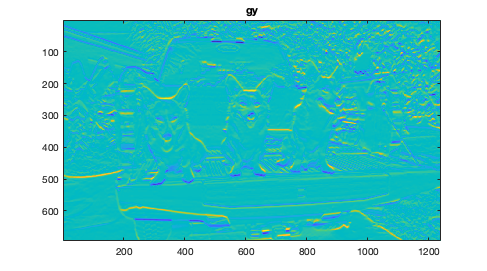

imagesc(gyIm);
title('gy');

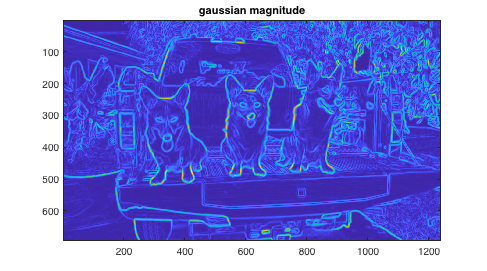

imagesc(magIm);
title('gaussian magnitude')

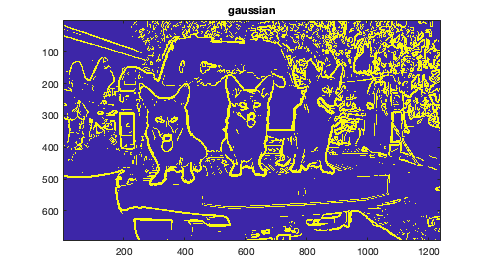

%%% 4. %%%
T = 0.025;
tIm = magIm > T;
imagesc(tIm);
title('gaussian')

It was interesting to see how the sigma value changed the size/shape of the edges, because of the increased amount of blurring. By testing different values for sigma and T, I saw how difficult it is to choose appropriate values for both, to maximize edge detection while minimizing noise. I found that the edge detection worked well at a threshold of 0.025. 

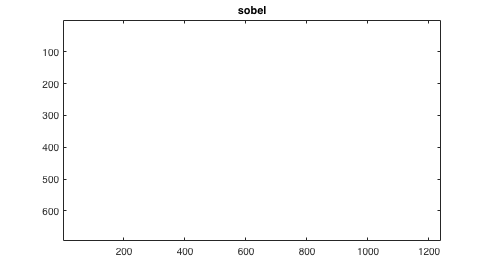

%%% 5. %%%
Fx = -fspecial('sobel')'; 
fxIm = imfilter(myIm,Fx); 
Fy = -fspecial('sobel'); 
fyIm = imfilter(myIm,Fy); 
magIm = sqrt(fxIm.^2 + fyIm.^2); 
tIm = magIm > 0.45; 
imagesc(tIm); 
title('sobel');

The sobel filter required much higher threshold levels than the gaussian to get the same results. The edges were thinner and had more noise than the gaussian, maybe because of the greater amount of smoothing that was applied by the gaussian. 

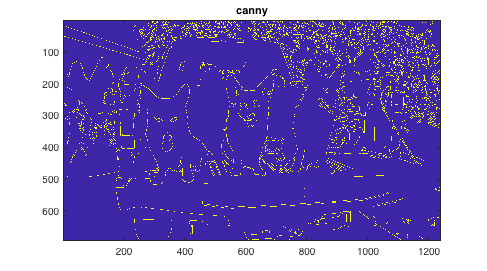

%%% 6. %%%
cannyIm = edge(myIm, 'canny', 0.3);
imagesc(cannyIm);
title('canny');

It was difficult to achieve good results with the canny filter. The edge lines were very faint and many significant edges were missing. Decreasing the threshold to try to get more information only lead to the introduction of large amounts of noise and not much better edge detection.

function [Gx, Gy] = gaussDeriv2D(sigma)
    x = 0:6*ceil(sigma);
    y = x';
    Gx = ((x-3*ceil(sigma))./(2*pi*sigma^4)).*(exp(-(((x-3*ceil(sigma)).^2+(y-3*ceil(sigma)).^2)./(2*sigma^2))));
    Gy = ((y-3*ceil(sigma))./(2*pi*sigma^4)).*(exp(-(((x-3*ceil(sigma)).^2+(y-3*ceil(sigma)).^2)./(2*sigma^2))));


    figure(1);
    surf(x, y, Gx);
    title("Gx");

    figure(2);
    surf(x, y, Gy);
    title("Gy");
end